z_rat = exp(11*pi*1i/12)

z_rat = -0.9659 + 0.2588i

t_0 = rand(1, 1)

t_0 = 0.4302

z_irr = exp(t_0*pi*1i)

z_irr = 0.2175 + 0.9761i

n = 60

n = 60

f = @(z) z^2

f = function_handle with value:
    @(z)z^2



L_rat = z_rat

L_rat = -0.9659 + 0.2588i

L_irr = z_irr

L_irr = 0.2175 + 0.9761i

for j = 2:n
    L_rat(j) = f(L_rat(j - 1));
    L_irr(j) = f(L_irr(j - 1));
end
L = [L_rat(1:12); L_rat(13:24); L_rat(25:36); L_rat(37:48); L_rat(49:60)]

L =   -0.9659 + 0.2588i   0.8660 - 0.5000i   0.5000 - 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i
  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i
  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.5000 + 0.8660i  -0.5000 - 0.8660i
  -0.5000 + 0.8660i  -0.5000 - 0.8660i  -0.4999 + 0.8661i  -0.5001 - 0.8660i  -0.4998 + 0.8662i  -0.5005 - 0.8657i  -0.4990 + 0.8666i  -0.5019 - 0.8649i  -0.4961 + 0.8683i  -0.5078 - 0.8615i  -0.4844 + 0.8750i  -0.5309 - 0.8477i
  -0.4367 + 0.9001i  -0.6194 - 0.7862i  -0.2344 + 0.9739i  -0.8935 - 0.4566i   0

L_irr'

ans = 	1.0e+05 *

   0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i


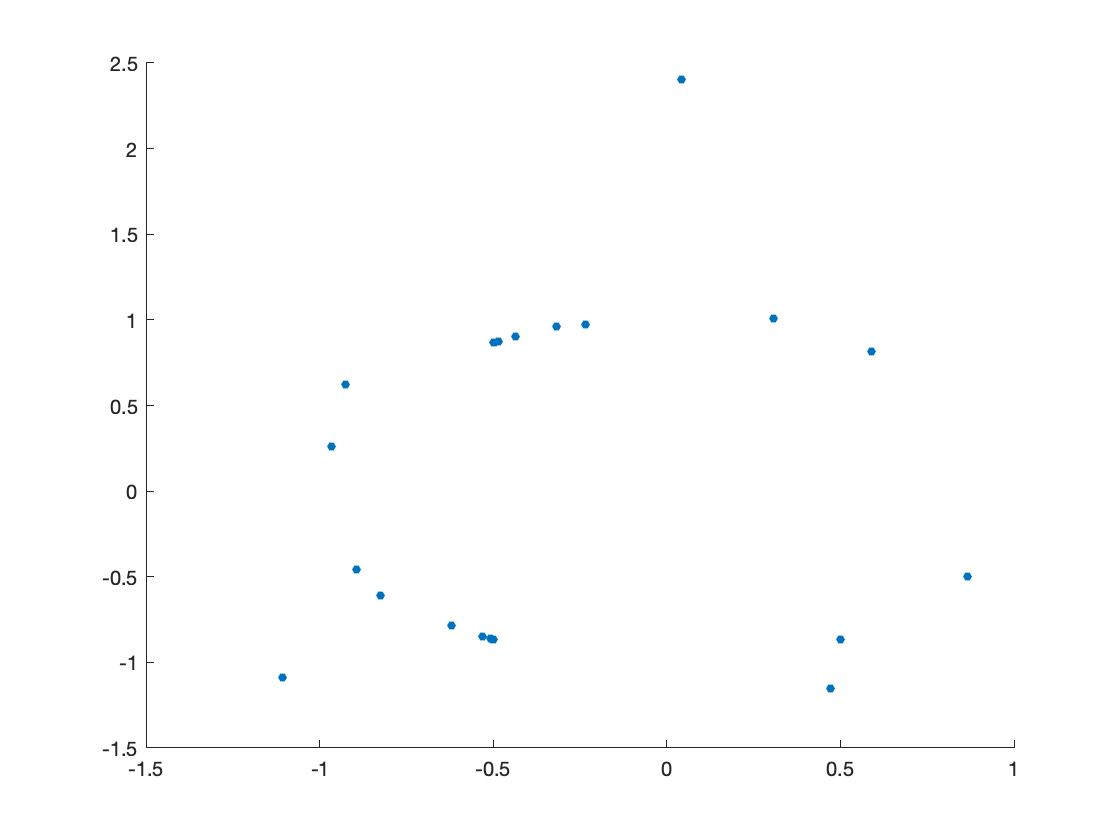

x_rat = real(L_rat);
y_rat = imag(L_rat);
x_irr = real(L_irr);
y_irr = imag(L_irr);
scatter(x_rat, y_rat, 20, 'filled')

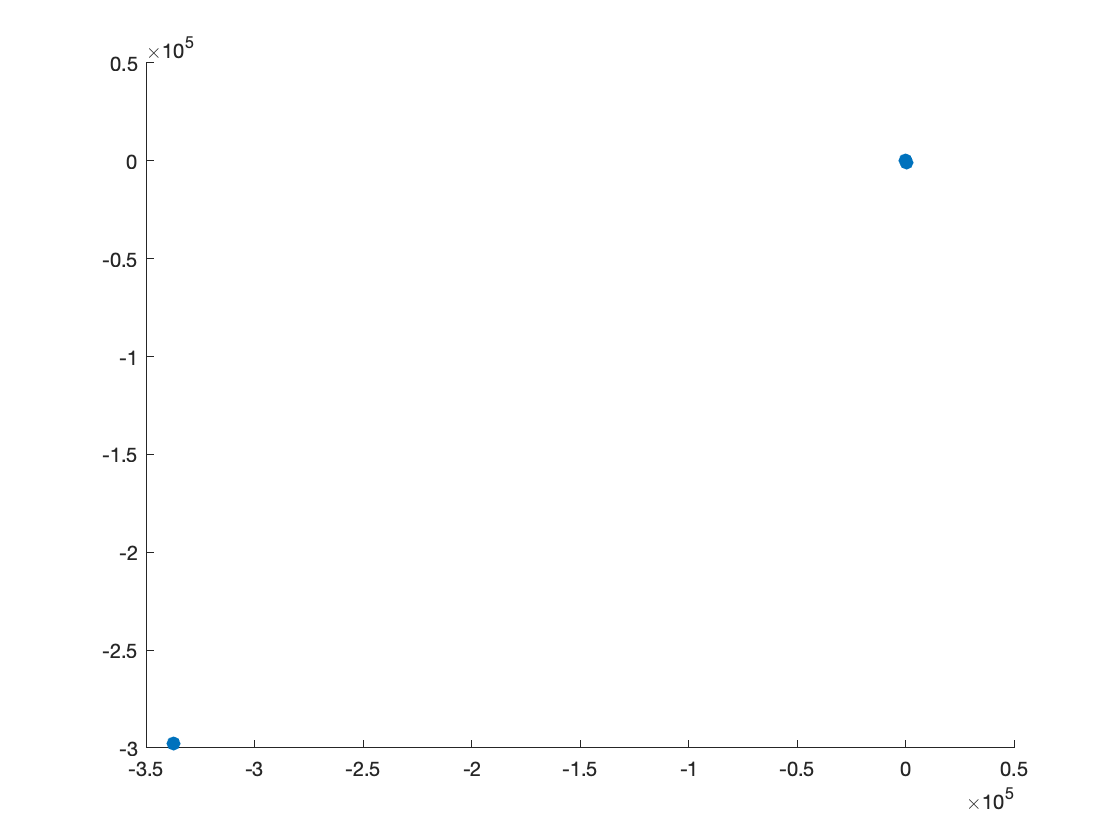

scatter(x_irr, y_irr, 50, 'filled')

We see that z_rat ends up bouncing between two values after a few applications of f, while z_irrat seems to continue generating new values. 